### **Fig 3**

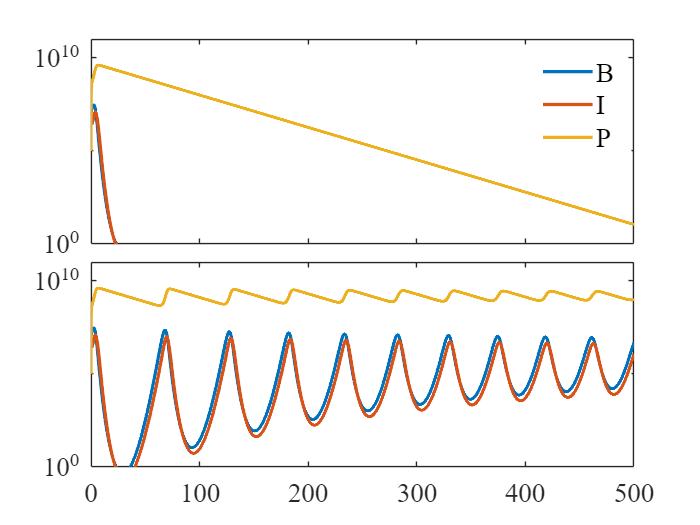

% Parameters
r = 1; 
K = 1;  
a = 0.06;    
Omega = 50;           
alpha = 2;
delta = 0.04;          

B0 = 0.1;     
I0 = 0.1;       
P0 = 0.001;    


tspan = [0 500];

y0 = [B0; I0; P0];

options = odeset('NonNegative', [1,2,3], 'RelTol', 1e-12,'MaxStep', 0.1);
[t1, y1] = ode15s(@(t,y) ode1B(t, y, r, K, a, Omega,alpha, delta), tspan, y0, options);
tout1 = t1;
yout1 = y1*1e8;
yout1(yout1<1)=0;
[t2, y2] = ode15s(@(t,y) ode1B_nothre(t, y, r, K, a, Omega,alpha, delta), tspan, y0, options);
tout2 = t2;
yout2 = y2*1e8;


% ===Visualization ===
FontSize = 16;
figure;


tl = tiledlayout(2, 1, 'TileSpacing', 'tight');

ax1 = nexttile;
semilogy(tout1, yout1(:,1:3), 'LineWidth', 2);
box on;
ylim([10^0, 10^11]);
xlim(tspan);


lgd = legend('B','I','P');
lgd.Location = 'northeast';
lgd.FontSize = FontSize;
lgd.Box = 'off';


ax1.FontName = 'Times New Roman';
ax1.FontSize = FontSize;
%ax1.LineWidth = 1;
ax1.XTickLabel = {};  


ax2 = nexttile;
semilogy(tout2, yout2(:,1:3), 'LineWidth', 2);
box on;
ylim([10^0, 10^11]);
xlim(tspan);

ax2.FontName = 'Times New Roman';
ax2.FontSize = FontSize;

%ax2.LineWidth = 1;

### Fig 4

clear; clc;

%Parameters
r = 1;         
K = 1;          
a = 0.06;       
Omega = 50;    
alpha = 2;
delta = 0.04;   

grid_size = 20; 

% Initial value range (log-uniform distribution)
B0_vec = logspace(-2, log10(0.5), grid_size);  % Bacteria
I0_vec = logspace(-2, log10(0.5), grid_size);  % Infected bacteria
P0_vec = logspace(-2, 0, grid_size);  % Phage

t_final = 500;         
extinct_thres = 1e-8;   

% (0 = Extinction, 1 = Coexistence)
state_matrix = zeros(length(P0_vec), length(I0_vec), length(B0_vec));


options = odeset('NonNegative', [1,2,3], 'RelTol', 1e-12,'MaxStep', 0.1);
tspan = [0, t_final];

for k = 1:grid_size
    fprintf('Progress: %.1f%%\n', 100*k/length(P0_vec)); 
    parfor i = 1:grid_size
        for j = 1:grid_size
            B0 = B0_vec(j);
            I0 = I0_vec(i);
            P0 = P0_vec(k);
            y0 = [B0; I0; P0];

        
            [~, y] = ode15s(@(t,y) ode1B(t, y, r, K, a, Omega, alpha, delta), ...
                tspan, y0, options);

            % Extract the last 10% portion to determine whether B is extinct
            n = size(y, 1);
            last_y = y(floor(n*0.9):end, 1);  

            if min(last_y(:)) < extinct_thres
                state_matrix(i,j,k) = 0; 
            else
                state_matrix(i,j,k) = 1; 
            end

        end
    end
end

Progress: 5.0%


Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 8).


Progress: 10.0%
Progress: 15.0%
Progress: 20.0%
Progress: 25.0%
Progress: 30.0%
Progress: 35.0%
Progress: 40.0%
Progress: 45.0%
Progress: 50.0%
Progress: 55.0%
Progress: 60.0%
Progress: 65.0%
Progress: 70.0%
Progress: 75.0%
Progress: 80.0%
Progress: 85.0%
Progress: 90.0%
Progress: 95.0%
Progress: 100.0%


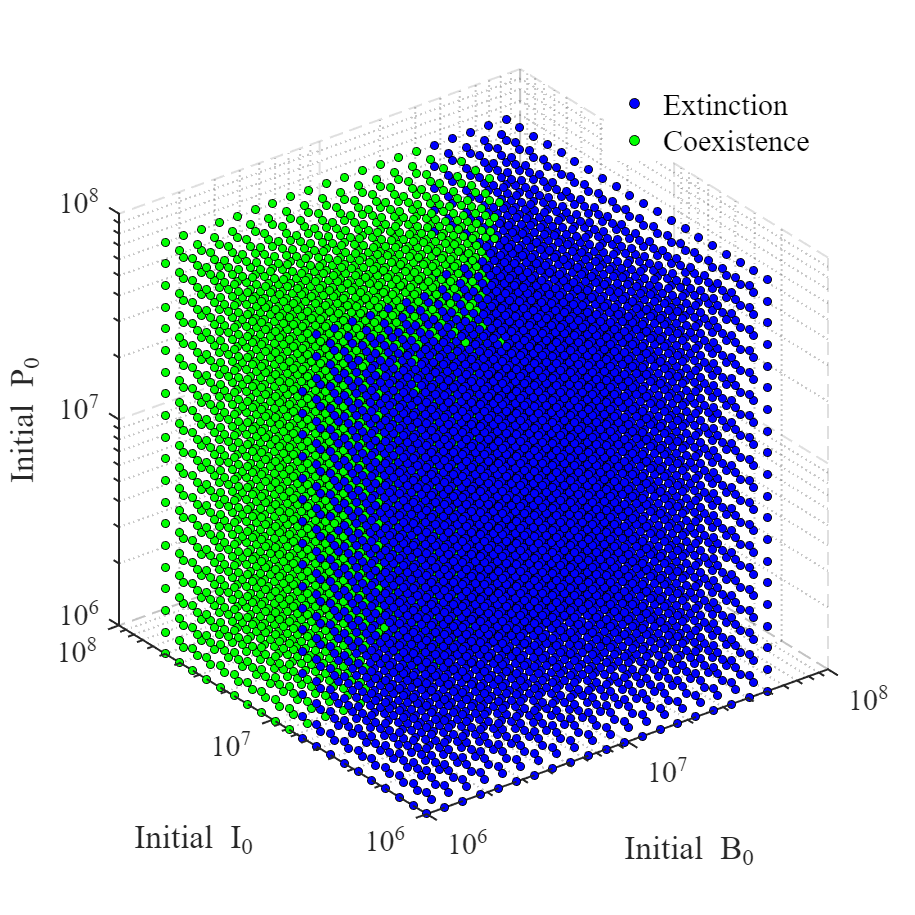


%save('state_matrix.mat', 'state_matrix');
% ===== Visualization =====
%load('state_matrix.mat');

width_cm = 4;
height_cm = 4;
width_inch = width_cm / 2.54;
height_inch = height_cm / 2.54;
dpi = 300;
fig = figure('Units', 'inches', 'Position', [1, 1, width_inch*dpi, height_inch*dpi]);
hold on;

[B0_grid, I0_grid, P0_grid] = meshgrid(B0_vec*10^8, I0_vec*10^8, P0_vec*10^8);

x = B0_grid(:);
y = I0_grid(:);
z = P0_grid(:);
states = state_matrix(:);

idx_extinct = (states == 0);
idx_coexist = (states == 1);

scatter3(x(idx_extinct), y(idx_extinct), z(idx_extinct), 24, 'b', 'filled', 'MarkerEdgeColor', 'k');
scatter3(x(idx_coexist), y(idx_coexist), z(idx_coexist), 24, 'g', 'filled', 'MarkerEdgeColor', 'k');

hold off;

fontSize = 18;  

xlabel('Initial B_0', 'FontSize', fontSize, 'FontName', 'Times New Roman');
ylabel('Initial I_0', 'FontSize', fontSize, 'FontName', 'Times New Roman');
zlabel('Initial P_0', 'FontSize', fontSize, 'FontName', 'Times New Roman');

legend('Extinction', 'Coexistence', 'Location', 'best', ...
    'FontSize', fontSize, 'FontName', 'Times New Roman', 'Box', 'off');

grid on;
set(gca, 'XScale', 'log', 'YScale', 'log', 'ZScale', 'log', ...
    'FontSize', fontSize, 'FontName', 'Times New Roman', ...
    'LineWidth', 1.2, 'GridLineStyle', '--');

view(3);
camlight;

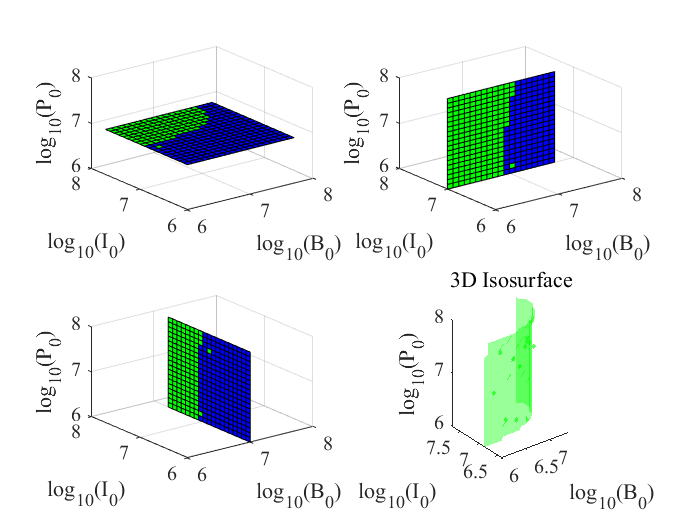


lighting gouraud;
%exportgraphics(fig, 'attractors_3D_scatter.svg', 'ContentType', 'vector');

figure;

[x, y, z] = meshgrid(log10(B0_vec*10^8), log10(I0_vec*10^8), log10(P0_vec*10^8));

fontSize = 12;

subplot(2,2,1);
slice(x, y, z, double(state_matrix), [], [], log10(0.1*10^8));
colormap([0 0 1; 0 1 0]);
xlabel('log_{10}(B_0)', 'FontSize', fontSize, 'FontName', 'Times New Roman');
ylabel('log_{10}(I_0)', 'FontSize', fontSize, 'FontName', 'Times New Roman');
zlabel('log_{10}(P_0)', 'FontSize', fontSize, 'FontName', 'Times New Roman');
set(gca, 'FontSize', fontSize, 'FontName', 'Times New Roman');

subplot(2,2,2);
slice(x, y, z, double(state_matrix), [], log10(0.1*10^8), []);
colormap([0 0 1; 0 1 0]);
%title('View 2: I_0 = 0.1', 'FontSize', fontSize, 'FontName', 'Times New Roman');
xlabel('log_{10}(B_0)', 'FontSize', fontSize, 'FontName', 'Times New Roman');
ylabel('log_{10}(I_0)', 'FontSize', fontSize, 'FontName', 'Times New Roman');
zlabel('log_{10}(P_0)', 'FontSize', fontSize, 'FontName', 'Times New Roman');
set(gca, 'FontSize', fontSize, 'FontName', 'Times New Roman');

subplot(2,2,3);
slice(x, y, z, double(state_matrix), log10(0.1*10^8), [], []);
colormap([0 0 1; 0 1 0]);
%title('View 3: B_0 = 0.1', 'FontSize', fontSize, 'FontName', 'Times New Roman');
xlabel('log_{10}(B_0)', 'FontSize', fontSize, 'FontName', 'Times New Roman');
ylabel('log_{10}(I_0)', 'FontSize', fontSize, 'FontName', 'Times New Roman');
zlabel('log_{10}(P_0)', 'FontSize', fontSize, 'FontName', 'Times New Roman');
set(gca, 'FontSize', fontSize, 'FontName', 'Times New Roman');

subplot(2,2,4);
p = patch(isosurface(x, y, z, double(state_matrix), 0.5));
set(p, 'FaceColor', 'g', 'EdgeColor', 'none', 'FaceAlpha', 0.4);
daspect([1 1 1])
view(3);
daspect([1 1 1]);
xlabel('log_{10}(B_0)', 'FontSize', fontSize, 'FontName', 'Times New Roman');
ylabel('log_{10}(I_0)', 'FontSize', fontSize, 'FontName', 'Times New Roman');
zlabel('log_{10}(P_0)', 'FontSize', fontSize, 'FontName', 'Times New Roman');
title('3D Isosurface', 'FontSize', fontSize, 'FontName', 'Times New Roman');
set(gca, 'FontSize', fontSize, 'FontName', 'Times New Roman');